clear all
warning('off','all')

rasta=20;
rast = 1:rasta;
[X,Y] = meshgrid(rast,rast);
points = [X(:)';Y(:)']; 

objects={}


objects =

  0×0 empty cell array



epsilon=0.0001

epsilon = 1.0000e-04

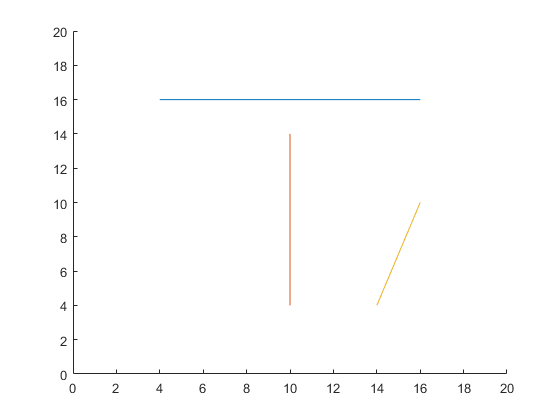

obj1.p1 = [0.2;0.8]*rasta+epsilon;
obj1.p2 = [0.8;0.8]*rasta+epsilon;
obj2.p1 = [0.5;0.7]*rasta+epsilon;
obj2.p2 = [0.5;0.2]*rasta+epsilon;
obj3.p1 = [0.7;0.2]*rasta+epsilon;
obj3.p2 = [0.8;0.5]*rasta+epsilon;

objects{1}=obj1;
objects{2}=obj2;
objects{3}=obj3;

 
figure;
axis([0 rasta 0 rasta])
hold on
for pp=1:size(objects,2)
plot([objects{pp}.p1(1) objects{pp}.p2(1)], [objects{pp}.p1(2) objects{pp}.p2(2)])
end
hold off;


% ------------------------parameters------------------------------

par.h=(rasta/2)^2;
par.price = 50;   %price per lamp
par.powercost = 100   %price per unit of power per year

par = struct with fields:
            h: 100
        price: 50
    powercost: 100


par.targetlum=1;    %
W = 0.05;             %weight of the financial cost

Maxlamps = 10;



minpower = 0.1;
maxpower = 2;
mincoord=rasta;
maxcoord=0;



% ------------------------initial population------------------------------

for i=1:PopSize
xcoord = mincoord+rand(1,Maxlamps)*(maxcoord-mincoord);
ycoord = mincoord+rand(1,Maxlamps)*(maxcoord-mincoord);
powerlevels = minpower+rand(1,Maxlamps)*(maxpower-minpower);
existence = randi([0 1], [1 Maxlamps]);
chromosome{i}=[xcoord; ycoord ;powerlevels;existence];
end

generation=[];

generation{1}.dna =chromosome;

exponent = (finalrate/Mutrate)^(1/MaxGen);



% ------------------------MAIN LOOP------------------------------
for igen= 1:MaxGen
    
    Mutrate = Mutrate*exponent;
    
    if mod(igen,10)==0
        disp(['Generation: ', num2str(igen)]);
        disp(['Mean fitness: ', num2str(mean(fitness))]);
    end
    
    % ------------------------evaluate fitness scores------------------------------
%     tic
    for j=1:PopSize
        chrom = generation{igen}.dna{j};
        
        fitness(j) = fitnessfunc(chrom, objects, points, par, W);
        
    end
    
    [sortedfitness,I] = sort(fitness);
    generation{igen}.fitness= fliplr(sortedfitness);
    generation{igen}.dna = generation{igen}.dna(fliplr(I));
    

    plot1(igen) = mean(fitness);
    plot2(igen) = sortedfitness(end);

%     toc
    % ------------------------selecting for breeding------------------------------
%     tic
    roulette = cumsum(generation{igen}.fitness)/sum(fitness);
    roulette(PopSize)=1;
 
    for k=1:PopSize-2
    index(k) = find(roulette>rand(),1);
    end
    
    pairs= reshape(index, [], 2);
    
%     toc
    % ------------------------ breeding------------------------------
%     tic
    for i=1:size(pairs,1)    
    [xx xy]= generation{igen}.dna{pairs(i,:)};

    crossover = randi(10);
    offpring1 = [xx(:,1:crossover) xy(:,crossover+1:end)];
    offpring2 = [xy(:,1:crossover) xx(:,crossover+1:end)];

    generation{igen+1}.dna{2*i-1}=offpring1;    
    generation{igen+1}.dna{2*i}=offpring2;
    end
%     toc
    % ------------------------mutation------------------------------
%     tic
    for p=1:PopSize-2
        mutindex = find(rand(1,Maxlamps)<Mutrate);
        if ~isempty(mutindex) 
            
            xcoord = mincoord+rand(1,size(mutindex,2))*(maxcoord-mincoord);
            ycoord = mincoord+rand(1,size(mutindex,2))*(maxcoord-mincoord);
            powerlevels = minpower+rand(1,size(mutindex,2))*(maxpower-minpower);
            existence = randi([0 1], [1 size(mutindex,2)]);
          
            generation{igen+1}.dna{p}(:,mutindex) =[xcoord; ycoord ;powerlevels;existence];
        
        end
    end
%     toc
    % ------------------------elitism------------------------------
    generation{igen+1}.dna{end+1}=generation{igen}.dna{1};   
    generation{igen+1}.dna{end+1}=generation{igen}.dna{2};
    
    
    % ------------------------stopping criteria------------------------------
%         if 0
%             break
%         end
end

Generation: 10


Mean fitness: 6.5183


Generation: 20


Mean fitness: 7.7828


Generation: 30


Mean fitness: 8.8696


Generation: 40


Mean fitness: 11.2106


Generation: 50


Mean fitness: 11.5025


Generation: 60


Mean fitness: 12.5822


Generation: 70


Mean fitness: 14.4506


Generation: 80


Mean fitness: 15.0612


Generation: 90


Mean fitness: 14.8343


Generation: 100


Mean fitness: 16.4384


chrom = generation{igen}.dna{1};
L=chrom(1:3,find(chrom(4,:)))

L =    18.3613    6.0374    5.4892   10.1357
    7.9731   16.7467    5.8716    9.8989
    0.7826    1.2497    1.1293    1.1390


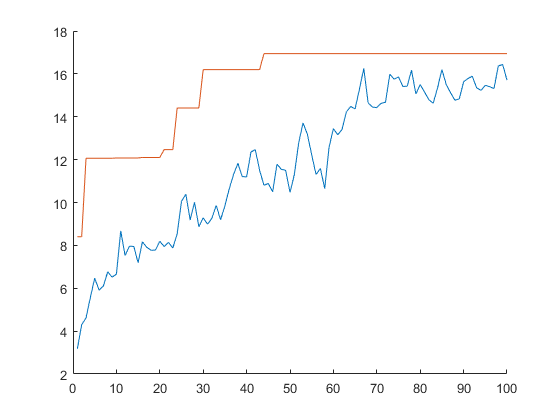


[fitness lum] = plotfunc(chrom, objects, points, par, W);
figure;
hold on
plot(plot1)
plot(plot2)
hold off

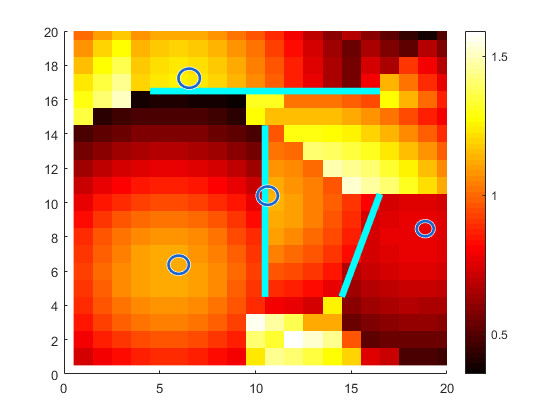


LIGHT = reshape(lum,[length(rast) length(rast)]);

figure;
hold on
% plot light
axis([0 rasta 0 rasta])
colormap('hot');             
imagesc(LIGHT);
colorbar;
% plot walls
for pp=1:size(objects,2)
pl0t =plot([objects{pp}.p1(1)+0.5 objects{pp}.p2(1)+0.5], [objects{pp}.p1(2)+0.5 objects{pp}.p2(2)+0.5]);
pl0t.LineWidth = 5;
pl0t.Color = 'cyan';
end
% plot lamps
for l=1:size(L,2)
viscircles([L(1,l)+0.5 L(2,l)+0.5],sqrt(L(3,l))/2,'Color',[0.1 0.4 0.8]);
end
hold off

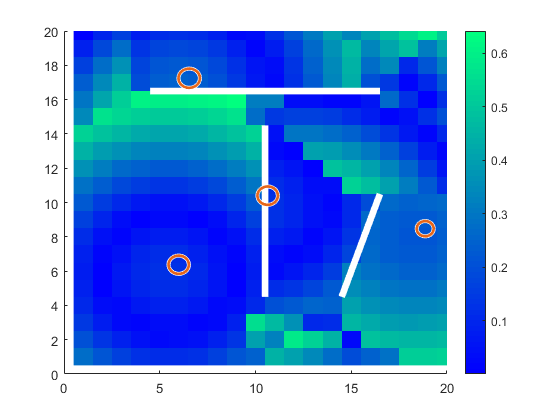


MAP = reshape(abs(lum-par.targetlum),[length(rast) length(rast)]);

figure;
hold on
% plot light
axis([0 rasta 0 rasta])
colormap('winter');             
imagesc(MAP);
colorbar;
% plot walls
for pp=1:size(objects,2)
pl0t =plot([objects{pp}.p1(1)+0.5 objects{pp}.p2(1)+0.5], [objects{pp}.p1(2)+0.5 objects{pp}.p2(2)+0.5]);
pl0t.LineWidth = 5;
pl0t.Color = 'white';
end
% plot lamps
for l=1:size(L,2)
viscircles([L(1,l)+0.5 L(2,l)+0.5],sqrt(L(3,l))/2,'Color',[0.9 0.4 0.1]);
end
hold off